## divide train set and test set

data = X;
label = y;

ratio = 0.8;
num_train = floor(length(label)*ratio); 
choose = randperm(length(label));

## cars 

vsels = [];
RMSECVs = [];
minRMSECVs = [];
iternum = 200;
RMSECV_min = 1;

for i = 1:iternum
    Cars = feature_cars(data(choose(1:num_train), :),...
                      label(choose(1:num_train)), 7, 5, 'center', 50);
    vsel_incre = Cars.vsel;
    minRMSECV_incre = Cars.minRMSECV;    
    RMSECV_incre = Cars.RMSECV;  
    
    vsels = [vsels, vsel_incre];
    RMSECVs = [RMSECVs, RMSECV_incre];
    minRMSECVs = [minRMSECVs, minRMSECV_incre];
    
    if minRMSECV_incre < RMSECV_min
        RMSECV_min = minRMSECV_incre;
        vsel_best = vsel_incre;
    end
    
end

The 10th variable sampling finished.
The 20th variable sampling finished.
The 30th variable sampling finished.
The 40th variable sampling finished.
The 50th variable sampling finished.
The 10th subset finished.
The 20th subset finished.
The 30th subset finished.
The 40th subset finished.
The 50th subset finished.
The 10th variable sampling finished.
The 20th variable sampling finished.
The 30th variable sampling finished.
The 40th variable sampling finished.
The 50th variable sampling finished.
The 10th subset finished.
The 20th subset finished.
The 30th subset finished.
The 40th subset finished.
The 50th subset finished.
The 10th variable sampling finished.
The 20th variable sampling finished.
The 30th variable sampling finished.
The 40th variable sampling finished.
The 50th variable sampling finished.
The 10th subset finished.
The 20th subset finished.
The 30th subset finished.
The 40th subset finished.
The 50th subset finished.
The 10th variable sampling finished.
The 20th variable 

vsel_best

vsel_best =     16    17    18    19    23    24    25    26    42    64   115   136   233   262   263   264   280   290   307   308   315   317   320   321


RMSECV_min

RMSECV_min =       0.28567


freqs = [];

for j = 1:length(effshift)
    freq = sum(vsels == j);
    freqs = [freqs, freq];
end

format short g

vsel = find(freqs >= floor(iternum * 0.5))

vsel =     16    17    18    19    23    24    25    26   205   262   263   264   280   290   291   307   308   316   317   320   321


effshift(vsel)

ans =        461.23       465.23       469.23       473.22       489.19       493.17       497.15       501.14       1178.6       1380.7       1384.1       1387.6       1443.2       1477.6       1481.1       1535.8       1539.2       1566.4       1569.8       1579.9       1583.3


CV = plscvfold(data(choose(1:num_train), vsel), label(choose(1:num_train)), 7);  

The 1th group finished.
The 2th group finished.
The 3th group finished.
The 4th group finished.
The 5th group finished.
The 6th group finished.
The 7th group finished.
The 8th group finished.
The 9th group finished.
The 10th group finished.


   
CV.RMSE_min

ans =        0.3137


CV.Rsquare_max     

ans =       0.92461


train_data  = data(choose(1:num_train), vsel_best);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), vsel_best);
test_label  = label(choose(num_train+1:end));

train_data  = data(choose(1:num_train), vsel);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), vsel);
test_label  = label(choose(num_train+1:end));

% box = [RMSECVs, RMSECVs_50, RMSECVs_100, RMSECVs_200, RMSECVs_5000];
% box_g = [zeros(size(RMSECVs)), ones(size(RMSECVs_50))*50,...
%     ones(size(RMSECVs_100))*100, ones(size(RMSECVs_200))*200,...
%     ones(size(RMSECVs_5000))*5000];
% 
% figure;
% boxplot(box, box_g);
% ylabel('RMSECVs')
% ylim([0.2, 0.5])

% Cars5000 = feature_cars(data(choose(1:num_train), :),...
%                       label(choose(1:num_train)), 7, 5, 'center', 5000);
% vsel_5000 = Cars5000.vsel;
% RMSECVs_5000 = Cars5000.RMSECV;

% Cars100 = feature_cars(data(choose(1:num_train), :),...
%                       label(choose(1:num_train)), 7, 5, 'center', 100);
% vsel_100 = Cars100.vsel;
% RMSECVs_100 = Cars100.RMSECV;

% Cars200 = feature_cars(data(choose(1:num_train), :),...
%                       label(choose(1:num_train)), 7, 5, 'center', 200);
% vsel_200 = Cars200.vsel;
% RMSECVs_200 = Cars200.RMSECV;

% Cars50 = feature_cars(data(choose(1:num_train), :),...
%                       label(choose(1:num_train)), 7, 5, 'center', 50);
% vsel_50 = Cars50.vsel;
% RMSECVs_50 = Cars50.RMSECV;

% format short g
% 
% bestaccs = [];
% bestcs = [];
% bestgs = [];
% 
% tic
% for i = [0.45, 0.5, 0.55, 0.6]
%     vsel = find(freqs >= floor(iternum * i))
%     train_data  = data(choose(1:num_train), vsel);
%     train_label = label(choose(1:num_train));
%     test_data   = data(choose(num_train+1:end), vsel);
%     test_label  = label(choose(num_train+1:end));
% 
%     [bestacc, bestc, bestg] = svm_gridsearch(train_label,...
%                         train_data, -2, 2, -2, 2, 5, 1, 1, 1);
%     bestaccs = [bestaccs, bestacc];
%     bestcs = [bestcs, bestc];
%     bestgs = [bestgs, bestg];
%        
% end
% toc
% 
% bestaccs
% bestcs
% bestgs


## grid search

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);
toc

*
optimization finished, #iter = 73
nu = 0.954248
obj = -6.771961, rho = -0.139703
nSV = 146, nBSV = 146
*
optimization finished, #iter = 52
nu = 0.676071
obj = -3.853390, rho = -0.019947
nSV = 102, nBSV = 100
*
optimization finished, #iter = 69
nu = 0.926174
obj = -6.791079, rho = -0.193481
nSV = 138, nBSV = 138
*
optimization finished, #iter = 55
nu = 0.765957
obj = -4.239125, rho = -0.058534
nSV = 109, nBSV = 107
*
optimization finished, #iter = 69
nu = 0.971831
obj = -7.682621, rho = -0.548258
nSV = 138, nBSV = 138
*
optimization finished, #iter = 67
nu = 0.978102
obj = -5.409357, rho = 0.118238
nSV = 134, nBSV = 134
Total nSV = 285
*
optimization finished, #iter = 73
nu = 0.960526
obj = -6.778028, rho = -0.138083
nSV = 146, nBSV = 146
*
optimization finished, #iter = 50
nu = 0.668321
obj = -3.714957, rho = 0.007054
nSV = 98, nBSV = 96
*
optimization finished, #iter = 69
nu = 0.925170
obj = -6.657789, rho = -0.187518
nSV = 137, nBSV = 135
*
optimization finished, #iter = 55
nu = 0.

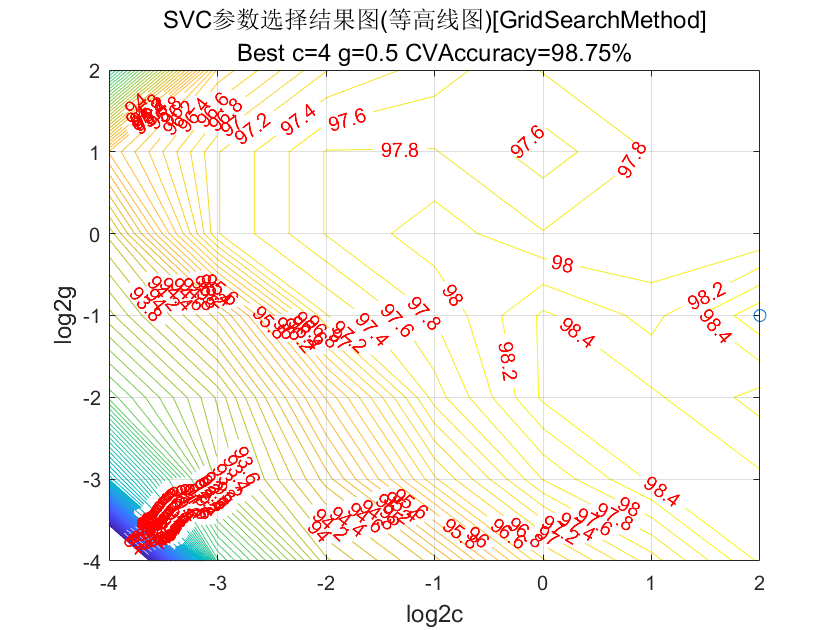

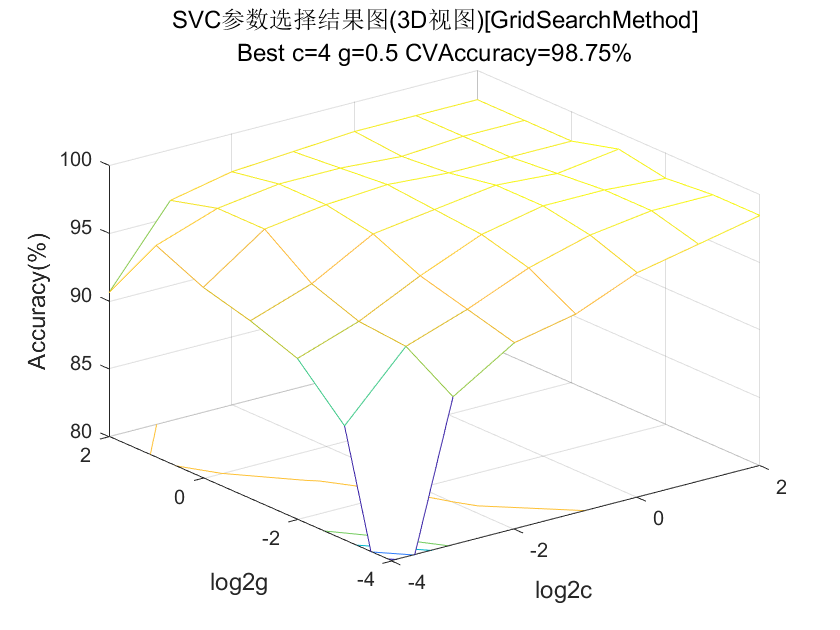

s = 0;
t = 0;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 


[train_pred_label, train_acc, ~]...

历时 2.912693 秒。


           = libsvmpredict(train_label, train_data, model);
[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);
toc

*
optimization finished, #iter = 104
nu = 0.018396
obj = -6.862511, rho = -2.343877
nSV = 6, nBSV = 1
*
optimization finished, #iter = 21
nu = 0.006806
obj = -2.218595, rho = -1.444457
nSV = 4, nBSV = 0
*
optimization finished, #iter = 99
nu = 0.099990
obj = -46.011310, rho = -7.709263
nSV = 20, nBSV = 13
*
optimization finished, #iter = 31
nu = 0.022161
obj = -6.930757, rho = 1.888822
nSV = 4, nBSV = 1
*.*
optimization finished, #iter = 233
nu = 0.086443
obj = -32.229929, rho = 2.766482
nSV = 17, nBSV = 11
*
optimization finished, #iter = 41
nu = 0.018212
obj = -7.444206, rho = -1.622421
nSV = 5, nBSV = 2
Total nSV = 47


tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...

Accuracy = 99.6875% (319/320) (classification)


                        train_data,-3, 2, -3, 2, 10, 0.1, 0.1, 0.1);
toc

Accuracy = 100% (80/80) (classification)


## train model

*
optimization finished, #iter = 74
nu = 0.954248
obj = -6.675977, rho = -0.115550
nSV = 146, nBSV = 146
*
optimization finished, #iter = 62
nu = 0.832263
obj = -4.802504, rho = -0.018059
nSV = 124, nBSV = 122
*
optimization finished, #iter = 69
nu = 0.926174
obj = -6.922630, rho = -0.244328
nSV = 138, nBSV = 138
*
optimization finished, #iter = 68
nu = 0.964539
obj = -5.544820, rho = -0.131246
nSV = 136, nBSV = 136
*
optimization finished, #iter = 69
nu = 0.971831
obj = -7.839022, rho = -0.661859
nSV = 138, nBSV = 138
*
optimization finished, #iter = 70
nu = 0.992701
obj = -6.477703, rho = 0.381909
nSV = 136, nBSV = 136
Total nSV = 286
*
optimization finished, #iter = 74
nu = 0.960526
obj = -6.676916, rho = -0.114845
nSV = 146, nBSV = 146
*
optimization finished, #iter = 62
nu = 0.821918
obj = -4.655900, rho = 0.003458
nSV = 120, nBSV = 120
*
optimization finished, #iter = 68
nu = 0.925170
obj = -6.787544, rho = -0.237021
nSV = 136, nBSV = 136
*
optimization finished, #iter = 67
nu = 

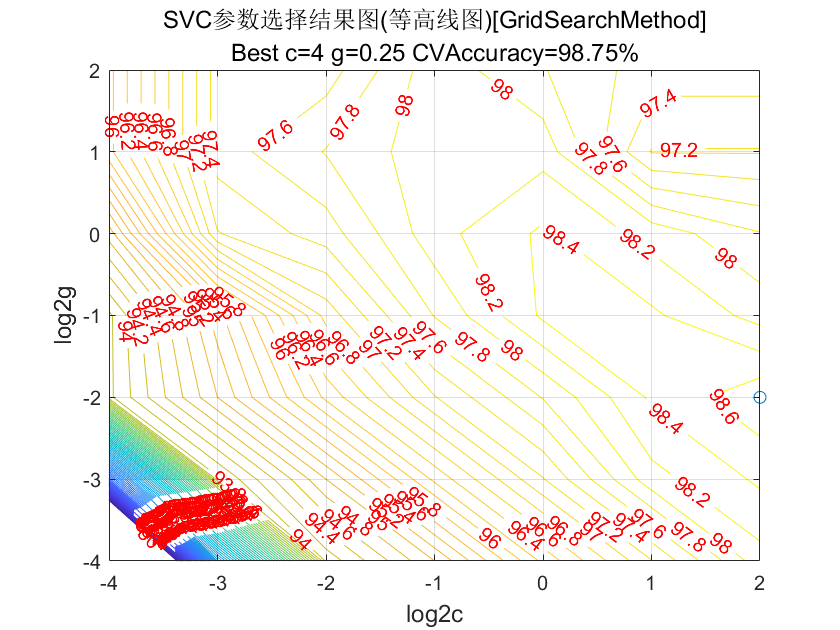

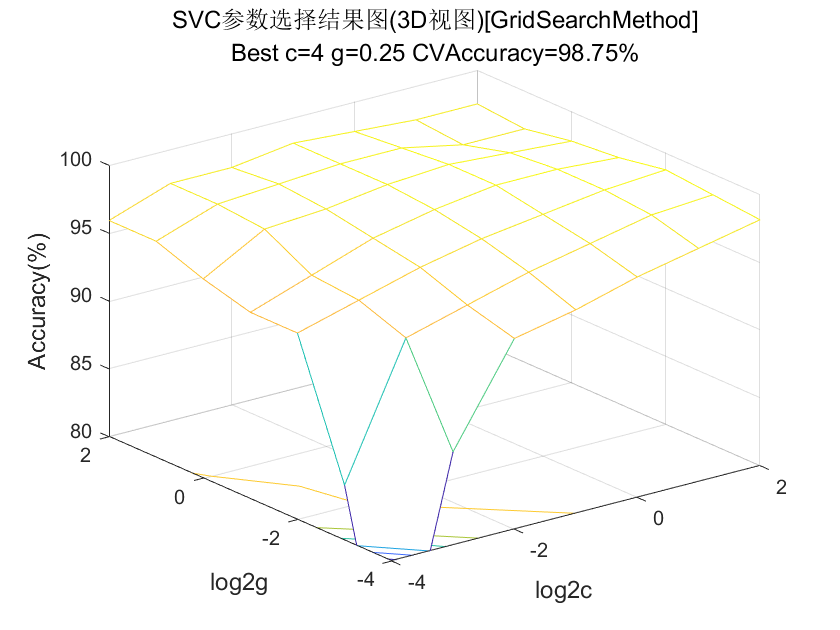

s = 0;
t = 0;
c = bestc;

g = bestg;

历时 2.755655 秒。


options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

## predict test set

*
optimization finished, #iter = 50
nu = 0.585416
obj = -7.213365, rho = -0.046839
nSV = 92, nBSV = 88
*
optimization finished, #iter = 30
nu = 0.390746
obj = -4.318473, rho = -0.020157
nSV = 58, nBSV = 56
*
optimization finished, #iter = 58
nu = 0.656194
obj = -9.229424, rho = -0.024545
nSV = 99, nBSV = 96
*
optimization finished, #iter = 38
nu = 0.473388
obj = -5.179347, rho = -0.136305
nSV = 69, nBSV = 66
*
optimization finished, #iter = 67
nu = 0.905868
obj = -11.658069, rho = -0.064332
nSV = 131, nBSV = 128
*
optimization finished, #iter = 51
nu = 0.624506
obj = -6.626909, rho = 0.198681
nSV = 86, nBSV = 84
Total nSV = 241
*
optimization finished, #iter = 50
nu = 0.590718
obj = -7.256934, rho = -0.042856
nSV = 91, nBSV = 88
*
optimization finished, #iter = 32
nu = 0.381160
obj = -4.161097, rho = 0.000332
nSV = 56, nBSV = 54
*
optimization finished, #iter = 52
nu = 0.648785
obj = -8.938452, rho = -0.038579
nSV = 97, nBSV = 93
*
optimization finished, #iter = 38
nu = 0.471554
obj = 

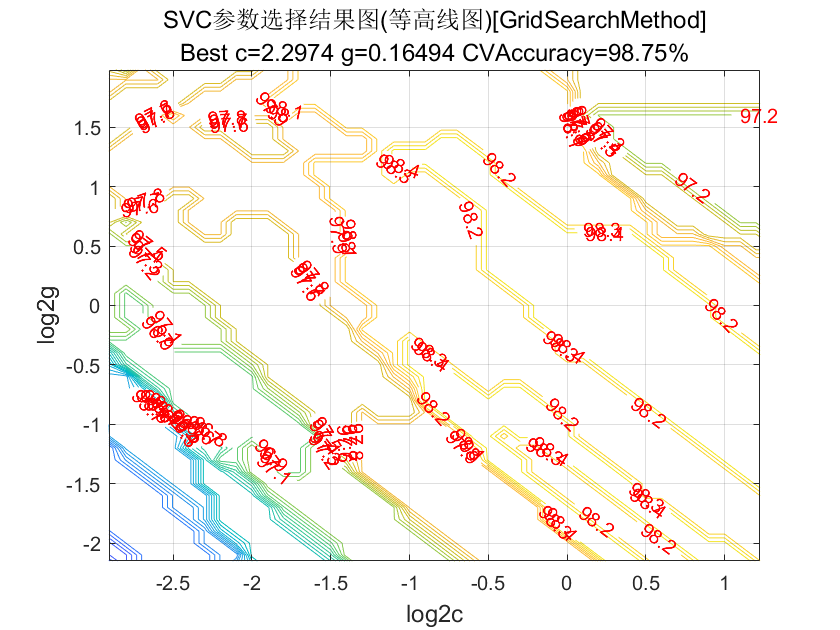

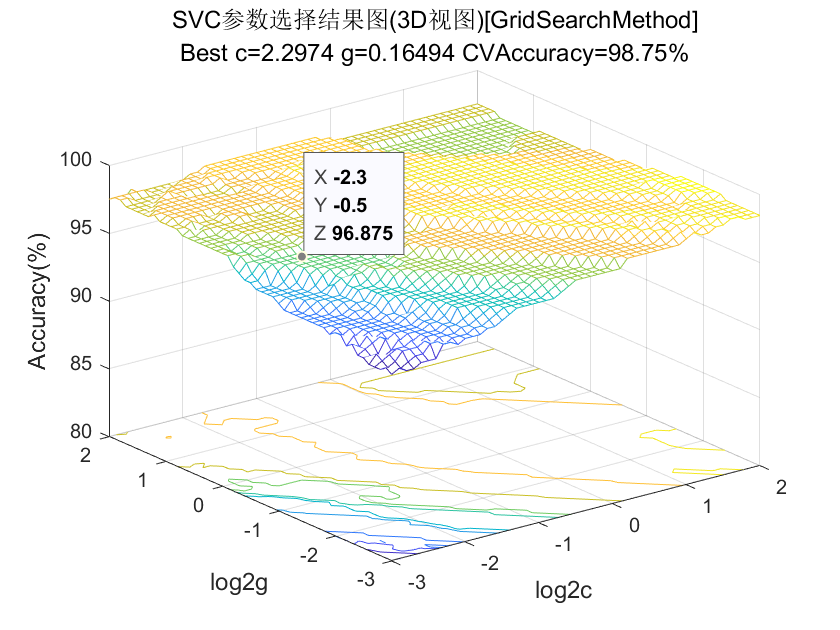

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

[test_pred_label, test_acc, ~]...

历时 126.640495 秒。


           = libsvmpredict(test_label, test_data, model);

## confusion matrix

% plotconfusion(test_label.', test_pred_label.');

# model = libsvmtrain(label, data, ‘option’)

# [predicted_label, accuracy,decision_values] = libsvmpredict(y_test, x_test, model)

% options:
% -s svm_type : set type of SVM (default 0)
% 	0 -- C-SVC		(multi-class classification)
% 	1 -- nu-SVC		(multi-class classification)
% 	2 -- one-class SVM
% 	3 -- epsilon-SVR	(regression)

.*
optimization finished, #iter = 180
nu = 0.026979
obj = -5.784098, rho = -2.237688
nSV = 8, nBSV = 3
*
optimization finished, #iter = 45
nu = 0.014241
obj = -2.804074, rho = -0.979764
nSV = 5, nBSV = 1
*.*
optimization finished, #iter = 197
nu = 0.127953
obj = -35.004835, rho = -5.957904
nSV = 27, nBSV = 20
*
optimization finished, #iter = 23
nu = 0.036043
obj = -8.515399, rho = 3.225917
nSV = 7, nBSV = 4
*
optimization finished, #iter = 71
nu = 0.111637
obj = -25.578405, rho = 2.059071
nSV = 20, nBSV = 16
*
optimization finished, #iter = 114
nu = 0.035016
obj = -7.558447, rho = -3.879100
nSV = 8, nBSV = 2
Total nSV = 65


% 	4 -- nu-SVR		(regression)
% -t kernel_type : set type of kernel function (default 2)
% 	0 -- linear: u'*v
% 	1 -- polynomial: (gamma*u'*v + coef0)^degree

Accuracy = 99.0625% (317/320) (classification)


% 	2 -- radial basis function: exp(-gamma*|u-v|^2)
% 	3 -- sigmoid: tanh(gamma*u'*v + coef0)

Accuracy = 100% (80/80) (classification)


% 	4 -- precomputed kernel (kernel values in training_set_file)
% -d degree : set degree in kernel function (default 3)
% -g gamma : set gamma in kernel function (default 1/num_features)  
%            gamma越大，支持向量越少，过拟合
% -r coef0 : set coef0 in kernel function (default 0)
% -c cost : set the parameter C of C-SVC, epsilon-SVR, and nu-SVR (default 1)
%           C是惩罚系数（正则化参数的倒数），即对误差的宽容度，c越大，容易过拟合
% -n nu : set the parameter nu of nu-SVC, one-class SVM, and nu-SVR (default 0.5)
% -p epsilon : set the epsilon in loss function of epsilon-SVR (default 0.1)
% -m cachesize : set cache memory size in MB (default 100)
% -e epsilon : set tolerance of termination criterion (default 0.001)
% -h shrinking : whether to use the shrinking heuristics, 0 or 1 (default 1)
% -b probability_estimates : whether to train a SVC or SVR model for probability estimates, 0 or 1 (default 0)
% -wi weight : set the parameter C of class i to weight*C, for C-SVC (default 1)
% -v n: n-fold cross validation mode(default 5)
% -q : quiet mode (no outputs)

% iter为迭代次数，
% nu 与前面的操作参数-n nu 相同，
% obj为SVM文件转换为的二次规划求解得到的最小值，
% rho 为判决函数的常数项b，
% nSV 为支持向量个数，
% nBSV为边界上的支持向量个数，
% Total nSV为支持向量总个数。
% 训练后的模型保存为文件*.model，用记事本打开其内容如下：
% svm_type c_svc % 训练所采用的svm类型，此处为C- SVC
% kernel_type rbf %训练采用的核函数类型，此处为RBF核
% gamma 0.0769231 %设置核函数中的g ，默认值为1/ k
% nr_class 2 %分类时的类别数，此处为两分类问题
% total_sv 132 %总共的支持向量个数
% rho 0.424462 %决策函数中的常数项b
% label 1 -1%类别标签
% nr_sv 64 68 %各类别标签对应的支持向量个数